%rmpath('C:\Program Files\MATLAB\R2023b\toolbox\fieldtrip-20180701\external\spm8');
%savepath;

%import toolboxes
addpath( genpath('C:\Program Files\MATLAB\R2023b\toolbox\ft4topo')); % Datenpfad
addpath(genpath('C:\Program Files\MATLAB\R2023b\toolbox\NoiseTools')); % Datenpfad
addpath( genpath('C:\Program Files\MATLAB\R2023b\toolbox\scripts_duerschmid')); % Datenpfad

%DATA
FifFile = {'D:\Dokumente\THU\Thesis\Bachelor\pre_filtered_data.fif'}

FifFile = 1×1 cell array
    {'D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif'}


% Read the header
header = ft_read_header(FifFile);

	306 MEG channel locations transformed
Reading D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif ...
Opening raw data file D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif...
	Range : 25000 ... 2135999  =     50.000 ...  4271.998 secs
Ready.


% Display the channel labels
disp('Channel labels:');

Channel labels:


disp(header.label);

    {'EOG002' }
    {'ECG003' }
    {'BIO004' }
    {'BIO005' }
    {'EEG001' }
    {'EEG002' }
    {'EEG003' }
    {'EEG004' }
    {'EEG005' }
    {'EEG006' }
    {'EEG007' }
    {'EEG008' }
    {'EEG009' }
    {'EEG010' }
    {'EEG011' }
    {'EEG012' }
    {'EEG013' }
    {'EEG014' }
    {'EEG015' }
    {'EEG016' }
    {'EEG017' }
    {'EEG018' }
    {'EEG019' }
    {'EEG020' }
    {'EEG021' }
    {'EEG022' }
    {'EEG023' }
    {'EEG024' }
    {'EEG025' }
    {'EEG026' }
    {'EEG027' }
    {'EEG028' }
    {'EEG029' }
    {'EEG030' }
    {'MEG0111'}
    {'MEG0112'}
    {'MEG0113'}
    {'MEG0121'}
    {'MEG0122'}
    {'MEG0123'}
    {'MEG0131'}
    {'MEG0132'}
    {'MEG0133'}
    {'MEG0141'}
    {'MEG0142'}
    {'MEG0143'}
    {'MEG0211'}
    {'MEG0212'}
    {'MEG0213'}
    {'MEG0221'}
    {'MEG0222'}
    {'MEG0223'}
    {'MEG0231'}
    {'MEG0232'}
    {'MEG0233'}
    {'MEG0241'}
    {'MEG0242'}
    {'MEG0243'}
    {'MEG0311'}
    {'MEG0312'}
    {'MEG0313'}
    {'MEG0321'}
    {'ME

addpath(genpath('C:\Program Files\MATLAB\R2023b\toolbox\fieldtrip-20180701'));  % Adds FieldTrip to the MATLAB path
ft_defaults;  % Initializes FieldTrip defaults
%initialize data structures
meg.data = []; % hier legen wir eine structure an, in die die Daten geschrieben werden
eog.data = []; % hier legen wir eine structure an, in die die Daten geschrieben werden
trigchan = [];
%eeg.data = [];
ecg.data = [];

% Read header and recording information
meg.header = ft_read_header(FifFile);

	306 MEG channel locations transformed
Reading D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif ...
Opening raw data file D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif...
	Range : 25000 ... 2135999  =     50.000 ...  4271.998 secs
Ready.


srate = 500;
%eog.srate = meg.header.Fs;
%eeg.srate = meg.srate;
meg.channels = strmatch('MEG',meg.header.label); 
meg.channels = meg.channels(1:3:end); % Assuming you want every third channel
eog.channels = strmatch('EOG002', meg.header.label);
ecg.channels = strmatch('BIO004', meg.header.label);
%breath.channels = strmatch('BIO005', meg.header.label);
%eeg.channels = strmatch('EEG', meg.header.label);
%trigchan = find(strcmp('STI101', meg.header.label));

% Read data
X = single(ft_read_data(FifFile));

	306 MEG channel locations transformed
Reading D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif ...
Opening raw data file D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif...
	Range : 25000 ... 2135999  =     50.000 ...  4271.998 secs
Ready.
Reading 25000 ... 2135999  =     50.000 ...  4271.998 secs... [done]


meg.data = cat(2, meg.data, X(meg.channels, :));
ecg.data = cat(2, ecg.data, X(ecg.channels, :));
%eeg.data = cat(2, eeg.data, X(eeg.channels, :));
%trigchan = cat( 2,trigchan,X( end-2,: ));

% Clean up
clear X;
rmpath(genpath('C:\Toolbox\fieldtrip-20180701'));

%dimensions = size(trigchan);
% Display the dimensions
%disp('Dimensions of trigchan:');
%disp(dimensions);

ecg.data_t=ecg.data';
% Display the dimensions
dimensions=size(ecg.data_t)

dimensions =      2111000           1


disp('Dimensions of eog.data_t:');

Dimensions of eog.data_t:


disp(dimensions);

     2111000           1



meg.data_t=meg.data';

dimensions = size(meg.data_t);
% Display the dimensions
disp('Dimensions of meg.data:');

Dimensions of meg.data:


disp(dimensions);

     2111000         102



x=meg.data_t;
sr = 500;
ref=[];

x=nt_demean(x);
%ref=nt_demean(ref);
y=[ref,x];

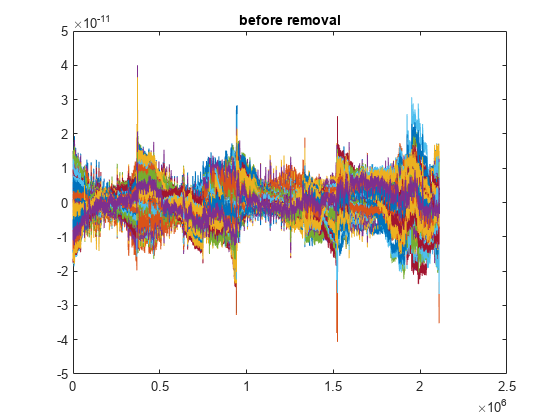

plot(x); title('before removal'); drawnow

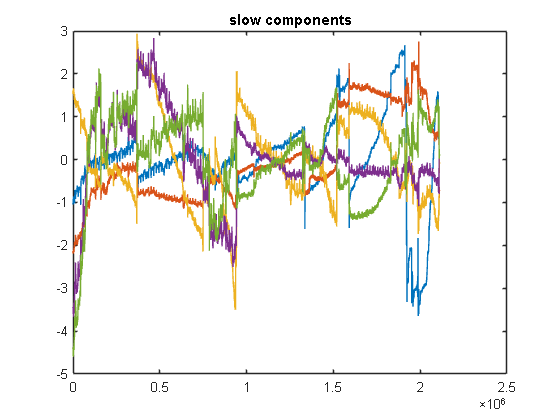

% remove slow comp
c0=nt_cov(y);
c1=nt_cov(diff(y)); % emphasizes high frequencies, slow components will be last
[todss,pwr0,pwr1]=nt_dss0(c0,c1);
figure(101); clf; plot(pwr1./pwr0,'.-'); ylabel('score'); xlabel('components'); title('DSS slow components');
z=nt_mmat(y,todss);
z=fliplr(z); % put slow first
NREMOVE=5; % based on examination of the cross-covariance matrix between z and ref        
figure(102); plot(nt_normcol(z(:,1:NREMOVE))); title('slow components');

y=nt_tsr(y,z(:,1:NREMOVE));
x=nt_tsr(x,z(:,1:NREMOVE));

% DSS remove power line
%c0=nt_cov(y);
%c1=nt_cov(nt_sparse_filter(y,[0; sr/50],[1; -1])); % bias suppresses DC & 50 Hz & harmonics
%[todss,pwr0,pwr1]=nt_dss0(c0,c1);
%figure(103); clf; plot(pwr1./pwr0,'.-'); ylabel('score'); xlabel('components'); title('DSS 50 Hz');
%figure(104); clf
%nt_spect_plot(x(1:10000,:),1024,[],[],sr); 
%z=nt_mmat(y,todss);
%z=fliplr(z); % put 50 Hz first       
%NREMOVE2=2;
%x=nt_tsr(x,z(:,1:NREMOVE2));
%hold on; nt_spect_plot(x(1:10000,:),1024,[],[],sr); set(gca,'xscale','log');
%title('DSS to remove 50 Hz components'); legend ('before', 'after');

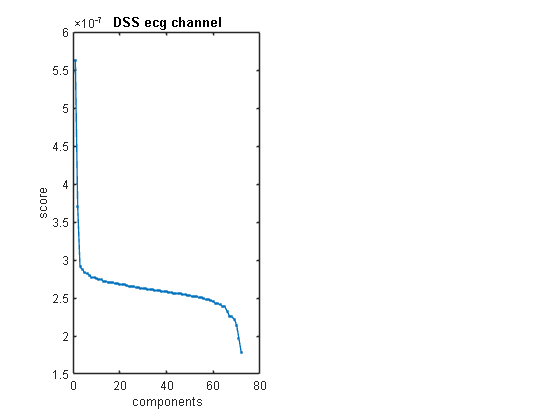

% remove eyeblink components
w=ecg.data_t;
w=mean(w,2);
c0=nt_cov(x);
c1=nt_cov(bsxfun(@times,x,w));
[todss,pwr0,pwr1]=nt_dss0(c0,c1);
figure(4); clf; 
subplot 121; plot(pwr1./pwr0,'.-'); ylabel('score'); xlabel('components'); title('DSS ecg channel');

z=nt_mmat(x,todss);

% repeat to tighten estimate
%w=abs(z(:,1))> 4*median(abs(z(:,1)));
%c0=nt_cov(x);
%c1=nt_cov(bsxfun(@times,x,w));
%[todss,pwr0,pwr1]=nt_dss0(c0,c1);
%subplot 122; plot(pwr1./pwr0,'.-'); ylabel('score'); xlabel('components'); title('DSS ecg 2');
%z=nt_mmat(x,todss);

NREMOVE3=3;
xx=nt_tsr(x,z(:,2:3));
figure(5); clf;
plot(xx); title('after ecg removal'); 
uicontrol('Visible','off')

plot(mean(z(:,1,:),3))
xlim([1 1000]); % Set the limits of the x-axis
uicontrol('Visible','off')

%save cleaned data "x"

save('dss_ecgchan_meg_data.mat', 'xx', '-v7.3');

% cut into epochs
%idxTrig=find(trigchan(1:end-1)<0.5 & trigchan(2:end)>0.5);
%PRE=round(sr*0.3); % pad to anchor detrending
%POST=round(sr*0.9); 
%nsamples=PRE+POST;
%nchans=size(x,2);
%ntrials=numel(idxTrig);
%xx=zeros(nsamples,nchans,ntrials); 
%for iTrial=6:ntrials-5
%    xx(:,:,iTrial)=x((idxTrig(iTrial)-PRE+1):(idxTrig(iTrial)+POST),:);
%end
%xx=nt_demean(xx);

% DSS to emphasize repeatablity
%[todss,pwr0,pwr1]=nt_dss1(xx);
%fromdss=pinv(todss);
%z=nt_mmat(xx,todss);
%figure(6); clf;
%plot(pwr1./pwr0,'.-'); xlabel('component'); ylabel('score'); title ('repeatability DSS');

%figure(7); clf;
%t=linspace(-PRE/sr,POST/sr,nsamples);
%nt_bsplot(z(:,1:5,:),[],[],t); title('best DSS component');
%xlabel('s')

%figure(8); clf
%plot(t,nt_normcol(mean(z(:,1:7,:),3))); title('DSS components 1:7'); xlabel('s');

% denoise by selecting best components and projecting back to sensor space
%NKEEP=7;
%yy=nt_mmat(xx,todss(:,1:NKEEP)*fromdss(1:NKEEP,:));

%figure(9); clf;
%subplot 121; plot(t,mean(xx,3)); title('before DSS denoising'); xlabel('s')
%subplot 122; plot(t,mean(yy,3)); title('after'); xlabel('s')

%plot(mean(z(:,1:5,:),3))

%save cleaned data "yy"

%save('dss_onecomp_eog_data.mat', 'yy', '-v7.3');